close("all"); clear; clc;

setmadsympath();
addpath("prydeMotorcycleStateSpace\");

## Parameters

### Sharp model parameters

Cdelta = 6.77;
Cf1 = 11174;
Cf2 = 938.6;
Cr1 = 15831;
Cr2 = 1325.6;
Ibxx = 31.18;
Ibxz = -1.7355;
Ibzz = 21.07;
Ihxx = 1.2338;
Ihzz = 0.442;
a = 0.9485376;
af0 = 0.02;
an = 0.1158;
ar0 = 0.02;
b = 0.4798;
e = 0.0244;
f = 0.0283;
g = 9.80665;
h = 0.6157;
ify = 0.7186;
iry = 1.0508;
mb = 217.45;
mh = 30.65;
rf = 0.3048;
rr = 0.3048;
tf = 0.05;
tr = 0.05;
caster = 0.4715;

### Center of mass

Ob = [b,0,h].';
Oa = [b,0,0].';
Ry = roty(rad2deg(-caster));
Oh = Oa + Ry*[a,0,0].';
m = mb + mh;
G = (mb.*Ob + mh.*Oh)./m;

### Normal forces

l = (a - an)/cos(caster);
p = b + l;
Zr = 1.428E03;
Zf = 1.005E03;

### Tire coefficients

Longitudinal :

kkf = 20;
kkr = 20;

Lateral :

kaf = Cf1/Zf;
klf = Cf2/Zf;
kar = Cr1/Zr;
klr = Cr2/Zr;

### Longitudinal displacement

p = b + (a - an)/cos(caster);
fw0 = (0.0085 + 0.018/p);
fw2 = 1.59E-06/p;

### Pryde parameters

params = @(v)[
    Cdelta;
    Ibxx;
    Ibxz;
    Ibzz;
    Ihxx;
    Ihzz;
    v;
    Zf;
    Zr;
    a;
    af0;
    an;
    ar0;
    b;
    e;
    f;
    fw0;
    fw2;
    g;
    h;
    ify;
    iry;
    kaf;
    kar;
    kkf;
    kkr;
    klf;
    klr;
    mb;
    mh;
    rf - tf;
    rr - tr;
    tf;
    tr;
    caster
    ];

## Model

nv = 1000;
vx = linspace(50,130,nv)./3.6;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

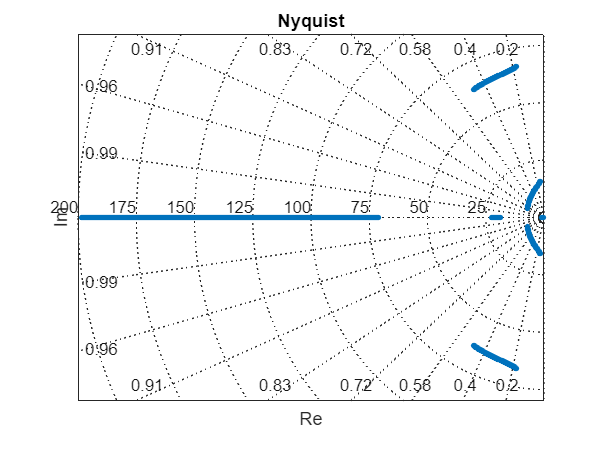

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

ns = 1E06;
t = linspace(0,2,ns);

Rr = rr + tr;
Rf = rf + tf;

x0 = @(v)[
    0;
    0;
    0;
    v;
    0;
    0;
    v/Rr;
    0;
    v/Rf
    ];

Plot impulse responses over speed :

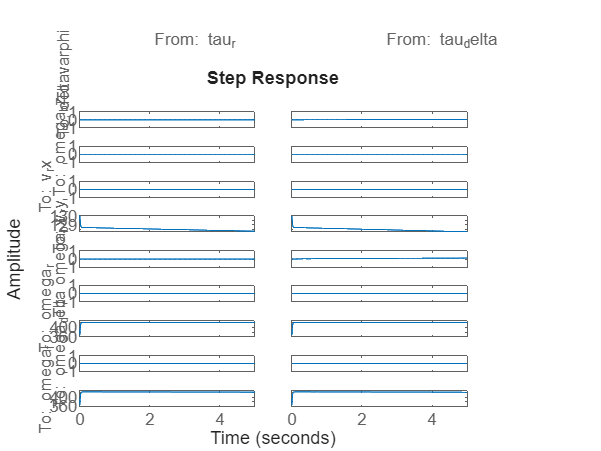

fig = figure();
tiledlayout(3,3);

mblue = "#0072BD";

cfg = RespConfig( ...
    "InitialState",x0(130) ...
    );

sys0 = sys{end};
step(sys0,[0,5],cfg);

rmpath("prydeMotorcycleStateSpace\")

function sys = plant(params)
    arguments
        params (35,1) double;
    end
    sys = prydeMotorcycleStateSpace(params);
end